# NR Positioning Using PRS

clc; clear; close all;
%% Configuration
% Initialize ellipsoid and geoid model
addpath('./utils');   % Adding functions folder to the path
addpath('./config');  % Make sure MATLAB can find config.m
run('config');        % Executes config.m and loads the variables into workspace

## 0) SIMULATION PARAMETERS

Specify the number of frames and the carrier frequency.

load(rxENUFile', 'receiverPositions', 'samplingRate');
load(nrLoSFile, 'LoSbStationsENU', 'LoSMatrix');
rng('default');                    % Set RNG state for repeatability
    % In meters. This local function assumes all gNB
                                   % heights to be 25m, as per TR 38.901 Table 7.4.1-1,
                                   % for 'UMa' path loss scenario              
gNBPos  = LoSbStationsENU;
numgNBs = size(LoSbStationsENU,1);

## 1) 5G Transmited signals Build

### 1.1 Carrier Configuration

% 2. Definir parámetros
nFrames      = 1; % Number of 10 ms frames
fc           = 38.5e9;       % Carrier frequency (Hz)
band         = 'n260';       % Banda NR
freqRange    = 'FR2';        % Rango de frecuencia
numerology   = 3;            % µ = 3
scs          = 15*(2^numerology);  % 120 kHz
slotPerFrame = 2^numerology*10; % 80 slots/frame
prsPower     = 0;            % Power
ssbParams    = struct( ...
    'BlockPattern', 'Case D', ...
    'PeriodSlots', 20, ...
    'BW', 400,... % 400 MHz bandwidth -> therefore 264 RB according to TS 38.104 Table 5.3.2-3
    'Power', 0, ...
    'KSSB', 0);

cellIds = randperm(1008,numgNBs) - 1;

% Configure carrier properties
carrierTemplate = nrCarrierConfig;
carrierTemplate.NSizeGrid   = 264;
carrierTemplate.SubcarrierSpacing   = scs;
    %carrierTemplate.SymbolsPerSlot      -> 14; BY DEFAULT
    %carrierTemplate.SlotsPerFrame       -> slotPerFrame; MANAGED BY LIBRARY
carrier = repmat(carrierTemplate,1,numgNBs);
for gNBIdx = 1:numgNBs
    carrier(gNBIdx).NCellID = cellIds(gNBIdx);
end

### 1.2 PRS Configuration

% --- gNBs visualization ---
% Group gNBs for better visualization
gnbs_per_occasion = 5;
groups = clusterBaseStationsMax3(gNBPos, gnbs_per_occasion);
% Visualize groups in a geomap
geoMap(gNBPos, groups)
numGroups = numel(groups);
fprintf('%d BaseStation clustered groups found.\n', numGroups);

8 BaseStation clustered groups found.



%% 4. Configure PRS per each base station
% PRS template
prs             = nrPRSConfig;
prsConfigs      = repmat(prs,1,numgNBs);

% --- PRS scheduling parameters ---
% Choose a PRS period (in slots) large enough to give each gNB a unique slot offset.
% With mu=3 (120 kHz), 1 slot = 0.125 ms, so:
% 160 slots = 20 ms, 320 slots = 40 ms, etc.
prsPeriodSlots = 160;
assert(prsPeriodSlots >= numgNBs, ...
    "prsPeriodSlots must be >= numgNBs to avoid PRS collisions with full-band PRS.");

prsSlotOffsets  = zeros(numgNBs,1);
prsRBOffsets    = zeros(numgNBs,1);
prsIDs          = randperm(4096,numgNBs) - 1;

fprintf('Proceding to assign a PRS set configuration for each BS\n');

Proceding to assign a PRS set configuration for each BS


% --- Assign one unique slot offset per gNB to avoid collisions ---
% Simple and robust mapping:
% gNB k transmits PRS at slotOffset = k-1 within the PRS period.
for gNBIdx = 1:numgNBs
    % --- PRS scheduling (time multiplexing) ---
    prs.PRSResourceSetPeriod   = [prsPeriodSlots 0];
    prs.PRSResourceOffset      = gNBIdx - 1;  % unique PRS occasion per gNB
    prs.PRSResourceRepetition  = 1;
    prs.PRSResourceTimeGap     = 1;

    % --- Muting patterns (optional, keep empty for now) ---
    prs.MutingPattern1 = [];
    prs.MutingPattern2 = [];

    % --- Full-band PRS frequency allocation ---
    prs.NumRB    = 264;   % 264
    prs.RBOffset = 0;

    % --- Resource element mapping ---
    prs.CombSize      = 6;
    prs.REOffset      = 0;       % keep constant; time-orthogonality already avoids collisions
    prs.NumPRSSymbols = 12;
    prs.SymbolStart   = 0;

    % --- PRS ID ---
    prs.NPRSID = prsIDs(gNBIdx);

    % Store
    prsConfigs(gNBIdx)     = prs;
    prsSlotOffsets(gNBIdx) = prs.PRSResourceOffset;
    prsRBOffsets(gNBIdx)   = prs.RBOffset;
end

### Path Loss Configuration

plCfg = nrPathLossConfig;
plCfg.Scenario = 'Uma';

## 1.3 Generate PRS and PDSCH Resources

fprintf('--- [5] Generating PRS-Only Resource Grids ---\n');

--- [5] Generating PRS-Only Resource Grids ---



totSlots = nFrames * carrier(1).SlotsPerFrame;
prsGrid  = cell(1, numgNBs);
dataGrid = cell(1, numgNBs);  % kept as zeros for compatibility (optional)

% Preallocate full multi-slot grids per gNB (K x L x totSlots)
for gNBIdx = 1:numgNBs
    % One slot grid dimensions for this carrier
    slotGrid0 = nrResourceGrid(carrier(gNBIdx), 1);
    [K, L] = size(slotGrid0);  % K: subcarriers, L: symbols per slot (=14)
    
    prsGrid{gNBIdx}  = complex(zeros(K, L*totSlots)); % concatenate slots along time (symbols)
    dataGrid{gNBIdx} = complex(zeros(K, L*totSlots)); % stays zero
end

for slotIdx = 0:totSlots-1
    [carrier(:).NSlot] = deal(slotIdx);

    for gNBIdx = 1:numgNBs
        % Generate PRS symbols and indices for this slot
        prsSym = nrPRS(carrier(gNBIdx), prsConfigs(gNBIdx));
        prsInd = nrPRSIndices(carrier(gNBIdx), prsConfigs(gNBIdx));

        % Slot grid
        slotGrid = nrResourceGrid(carrier(gNBIdx), 1);
        if ~isempty(prsInd)
            slotGrid(prsInd) = prsSym;
        end

        % Store into the preallocated multi-slot grid
        symStart = slotIdx * carrier(gNBIdx).SymbolsPerSlot + 1;
        symEnd   = symStart + carrier(gNBIdx).SymbolsPerSlot - 1;
        prsGrid{gNBIdx}(:, symStart:symEnd) = slotGrid;
        % dataGrid remains zeros
    end
end
fprintf('--- PRS-Only Resource Grid Generation Completed ---\n');

--- PRS-Only Resource Grid Generation Completed ---


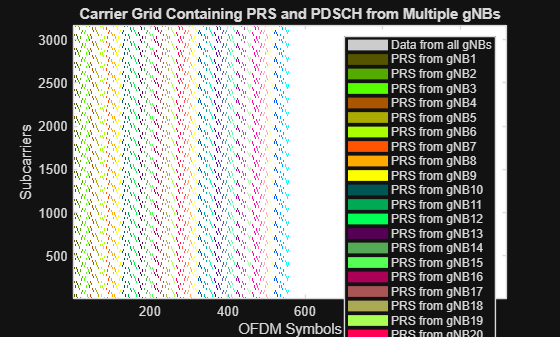

% Optional visualization (should still work if plotGrid expects both)
plotGrid(prsGrid, dataGrid);

## 1.4 Perform OFDM Modulation

% Perform OFDM modulation of PRS-only signal at each gNB
txWaveform = cell(1, numgNBs);

% Sanity: ensure consistent numerology across gNBs
assert(all([carrier.NSizeGrid] == carrier(1).NSizeGrid), "Inconsistent NSizeGrid across gNBs");
assert(all([carrier.SubcarrierSpacing] == carrier(1).SubcarrierSpacing), "Inconsistent SCS across gNBs");

% OFDM info (common)
ofdmInfo = nrOFDMInfo(carrier(1));

for gNBIdx = 1:numgNBs
    % No need to force NSlot here; grid already spans multiple slots
    txWaveform{gNBIdx} = nrOFDMModulate(carrier(gNBIdx), prsGrid{gNBIdx});
end

## **2) EPOCH EVALUATION**

Fs5g_pos = samplingRate/2;
Ts5g_pos = 1/Fs5g_pos;

step     = round(samplingRate/Fs5g_pos);
rxPos    = receiverPositions(1:step:end-1,:);
losMx    = LoSMatrix(1:step:end-1,:);

nBS      = length(LoSbStationsENU(:,1));
nEpochs  = size(receiverPositions,1);
nEpochs  = floor(nEpochs * Fs5g_pos/samplingRate);

epochEstim  = zeros(nEpochs,3);
epochError  = zeros(nEpochs,4);
epochNEstim = zeros(nEpochs,3);
epochNError = zeros(nEpochs,4);
tdoaEstim   = NaN(nEpochs,nBS);
tdoaError   = NaN(nEpochs,nBS);
    
addNoise = true;
SNRdB = 15;
cellsToBeDetected = 4;   % use >3 if available
c = physconst('LightSpeed'); % Speed of light in m/s

x0 = receiverPositions(1,:);

for epoch = 1:nEpochs
    UEPos = rxPos(epoch,:);
    vBS   = find(losMx(epoch,:) == 1);

    gNBPosEpoch = LoSbStationsENU(vBS,:);
    numAvail = numel(vBS); 
    if numAvail < 4
        fprintf('-------- %d has only %d BS so no estimation computed.\n', epoch, numAvail);
        continue;
    end

    % Stage A: build RX waveform for this epoch
    rxWaveform = synthesizeRxWaveform( ...
        txWaveform(vBS), gNBPosEpoch, UEPos, ...
        ofdmInfo, fc, plCfg, addNoise, SNRdB);

    % Stage B: estimate ToA
    [toa, maxCorr] = estimateToA(rxWaveform, carrier(vBS), prsGrid(vBS), ofdmInfo);

    % Stage C: solve TDOA using detected set
    [estimatedPos, tdoa] = solveTDOA(toa, gNBPosEpoch, x0);
    x0 = estimatedPos;
    % Save results
    epochEstim(epoch,:) = estimatedPos(:).';
    errVec = estimatedPos(:).' - UEPos;
    epochError(epoch,:) = [errVec, norm(errVec)];

    % Ground-truth RTDOA
    dist    = vecnorm(gNBPosEpoch - UEPos, 2, 2);
    rtoa    = dist / c;
    rtdoa   = (rtoa(2:end) - rtoa(1));
    % --- Save TDOA estimates and errors ---
    tdoaEstim(epoch, vBS(2:end))    = tdoa;
    timerror                        = rtdoa - tdoa.';
    tdoaError(epoch, vBS(2:end))    = timerror;
    if any(isnan(tdoa))
        error('La diferencia TDOA supera el umbral de 15e9');
    end
    fprintf('%d Has been computed with an absolute error of %f.\n', epoch, norm(errVec));
end

1 Has been computed with an absolute error of 0.465136.
2 Has been computed with an absolute error of 0.228949.
3 Has been computed with an absolute error of 0.318167.
4 Has been computed with an absolute error of 0.959002.
5 Has been computed with an absolute error of 0.305548.
6 Has been computed with an absolute error of 1.037184.
7 Has been computed with an absolute error of 0.256916.
8 Has been computed with an absolute error of 0.482576.
9 Has been computed with an absolute error of 1.577703.


## **3) Results Saving**

save(nrSimFile, 'epochEstim','epochError', 'epochNEstim', 'epochNError','Ts5g_pos');
save(nrObsFile, 'tdoaEstim', 'tdoaError');